##     Model linearisation

% Model linearisation
step_size = 1e-7; 
u = 20;  % velocity to linearise about 
[theta_LR, theta_UR, theta_1s, theta_1c, phi, theta, delta_E, delta_R] = F_fsolve(u);


                                        First-order                     Norm of 
 Iteration  Func-count   ||f(x)||^2      optimality       Lambda           step
     0           9      3.81662e+09        5.56e+13         0.01
     1          18      1.66511e+08        7.01e+09        0.001       0.164363
     2          27            32574        9.84e+07       0.0001      0.0280616
     3          36         0.477134        4.11e+05        1e-05    0.000995152
     4          45      1.43961e-07             228        1e-06    2.22211e-06
     5          54      5.12108e-12            1.36        1e-07    9.29053e-10

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the pr

state = [u, 0, 0, 0, 0, 0, phi, theta, 0];
ctrl = [theta_LR, theta_UR, theta_1s, theta_1c, delta_E, delta_R];

% average mass, CG and moment of inertia during patient transport
params = [1524, 2630.668, 9.80665, 0.52992, 0.682, 0.682, 5.5, 5.5];

% for linearisation
theta_0 = 0.5 * (theta_LR + theta_UR);
theta_diff = 0.5 * (theta_UR - theta_LR);
ctrl_trans = [theta_0, theta_diff, theta_1s, theta_1c, delta_E, delta_R];

% Make sure this is very close to 0 so we are trim the helicopter
xdot = stateDerivative(state, ctrl_trans, params)

xdot = 1.0e-08 *

    0.0063
   -0.0013
   -0.0028
    0.1583
    0.0015
    0.0606
         0
         0
         0



[A, B, A_lon, B_lon, A_lat, B_lat] = Linearisation(state, ctrl, params, step_size)

A =    -0.0174   19.9994  -19.9507         0  -20.0000   20.0000         0   -4.0593         0
  -20.0000   -0.0018   20.0242   20.0000         0  -20.0000    1.6331   -8.1735         0
   19.7422  -19.9999   -0.9431  -20.0000   20.0000         0   -3.6535   -3.6718         0
    1.4047    0.0005    1.2935    0.8093   18.6957   17.8863         0         0         0
    0.0699    0.0004   -0.0362    0.6669         0   26.4189         0         0         0
    0.5391    0.0002    0.5001  -19.5888  -20.3981   -0.8093         0         0         0
         0         0         0    1.0000    2.0424    0.9129  -22.5892  158.6525         0
         0         0         0         0    0.4081   -0.9129  -26.4205         0         0
         0         0         0         0    2.2372    1.0000  -24.7432  144.8410         0


B =     6.2234   10.3804  -10.1833    6.8097         0   -0.0004
    3.8654    5.5971    5.6349    8.3295         0   -0.6091
 -211.5532   -5.8789  -27.0751   -5.2432   -0.6669         0
  129.4544  -24.3335  246.3786  395.9806         0   -0.4838
   -3.5560   -2.0442  -13.9086    8.4624   -0.2798    0.0000
   50.0842   -9.3061   94.3995  151.6096         0   -0.3372
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


A_lon =    -0.0174  -19.9507  -20.0000   -4.0593
   19.7422   -0.9431   20.0000   -3.6718
    0.0699   -0.0362         0         0
         0         0    0.4081         0


B_lon =     6.2234  -10.1833         0
 -211.5532  -27.0751   -0.6669
   -3.5560  -13.9086   -0.2798
         0         0         0


A_lat =    -0.0018   20.0000  -20.0000    1.6331         0
    0.0005    0.8093   17.8863         0         0
    0.0002  -19.5888   -0.8093         0         0
         0    1.0000    0.9129  -22.5892         0
         0         0    1.0000  -24.7432         0


B_lat =     5.5971    8.3295   -0.6091
  -24.3335  395.9806   -0.4838
   -9.3061  151.6096   -0.3372
         0         0         0
         0         0         0


## State-space objects

% Define C and D matrices for attitude and velocity
C_long_att = [0 0 0 1];  % output theta for longitudinal attitude controller
C_lat_att = [0 0 0 1 0;
             0 0 0 0 1];  % output phi & psi for lateral attitude controller
D_long_att = [0 0 0];
D_lat_att = [0 0 0;
             0 0 0];
C_test = [1 0 0 0 0 0 0 0 0;
          0 1 0 0 0 0 0 0 0;
          0 0 1 0 0 0 0 0 0;
          0 0 0 0 0 0 1 0 0;
          0 0 0 0 0 0 0 1 0;
          0 0 0 0 0 0 0 0 1];

% Velocity matrices
C_long_vel = [1 0 0 0;
              0 1 0 0];  % output u & w
C_lat_vel = [1 0 0 0 0];  % output v
D_long_vel = [0 0 0;
              0 0 0];
D_lat_vel = [0 0 0];
D_test = zeros(6, 6);

% complete ss
ss_c = ss(A, B, C_test, D_test);
ss_c.StateName = {'u-vel'; 'v-vel'; 'w-vel'; 'roll rate'; 'pitch rate'; 'yaw rate'; 'roll angle'; 'pitch angle'; 'yaw angle'};
ss_c.InputName = {'theta_0'; 'Delta_theta'; 'theta_{1s}'; 'theta_{1c}'; 'delta_E'; 'delta_R'};
ss_c.OutputName = {'u-vel'; 'v-vel'; 'w-vel'; 'phi'; 'theta'; 'psi'};

% attitude ss
ss_long_att = ss(A_lon, B_lon, C_long_att, D_long_att);
ss_lat_att = ss(A_lat, B_lat, C_lat_att, D_lat_att);

% velocity ss
ss_long_vel = ss(A_lon, B_lon, C_long_vel, D_long_vel);
ss_lat_vel = ss(A_lat, B_lat, C_lat_vel, D_lat_vel);

% adjusting state names
ss_long_att.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};
ss_long_vel.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};

ss_lat_att.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};
ss_lat_vel.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};

% adjusting control variable names
ss_long_att.InputName = {'theta_0'; 
                          'theta_{1s}';
                          'delta_e'};
ss_long_vel.InputName = {'theta_0'; 
                          'theta_{1s}';
                          'delta_e'};
ss_lat_att.InputName = {'Delta_theta';
                          'theta_{1c}';
                          'delta_r'};
ss_lat_vel.InputName = {'Delta_theta';
                          'theta_{1c}';
                          'delta_r'};

% assign output variable names
ss_long_att.OutputName = {'theta'};
ss_long_vel.OutputName = {'u-vel'; 'w-vel'};
ss_lat_att.OutputName = {'phi'; 'psi'};
ss_lat_vel.OutputName = {'v-vel'};

### Longitudinal control (attitude and velocity)

There are two unstable oscillatory poles with a natural frequency of 0.383 rad/s. This can be seen in the resonant peak in the Bode diagrams later.

% Look at the poles and zeros
% Create separate plants
% P_whole = tf(ss_c)

P_pitch = tf(ss_long_att); P_pitch = P_pitch(1, 2)  % mapping longitudinal cyclic pitch to pitch angle


P_pitch =
 
  From input "theta_{1s}" to output "theta":
          -5.676 s^2 - 5.342 s - 2218
  --------------------------------------------
  s^4 + 0.9605 s^3 + 396 s^2 + 14.98 s - 3.163
 
Continuous-time transfer function.
Model Properties


pitch_zeros = tzero(P_pitch({'theta'}, 'theta_{1s}'))

pitch_zeros =   -0.4706 +19.7605i
  -0.4706 -19.7605i


damp(P_pitch)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  7.24e-02                -1.00e+00       7.24e-02        -1.38e+01    
 -1.10e-01                 1.00e+00       1.10e-01         9.07e+00    
 -4.61e-01 + 1.99e+01i     2.32e-02       1.99e+01         2.17e+00    
 -4.61e-01 - 1.99e+01i     2.32e-02       1.99e+01         2.17e+00    



% 
% P_uw = tf(ss_long_vel); P_uw = P_uw(1, 2);  % mapping longitudinal cyclic pitch to u-velocity
% tzero(P_uw({'u-vel'}, 'theta_{1s}'));
% damp(P_uw);
% 
% P_roll = tf(ss_lat_att); P_roll = P_roll(1, 2);
% tzero(P_roll({'phi'}, 'theta_{1c}'));
% damp(P_roll);

### Open loop pitch response

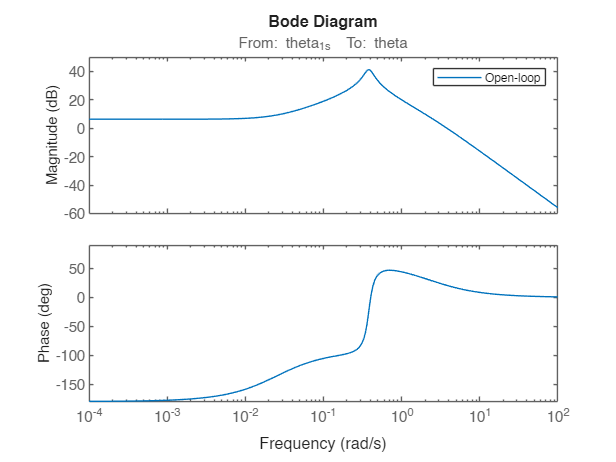

bode(P_pitch, {1e-4, 1e2})

legend("Open-loop")

allmargin(P_pitch)

ans = struct with fields:
     GainMargin: 0.483308509269414
    GMFrequency: 0
    PhaseMargin: -1.593316978981258e+02
    PMFrequency: 3.817275521425779
    DelayMargin: 0.917492739627089
    DMFrequency: 3.817275521425779
         Stable: 0


% Loop shaping notes
% tf(makeweight(0.5, 20, 20))#
w3_tester = tf(W3_pitch);

### Using mixsyn

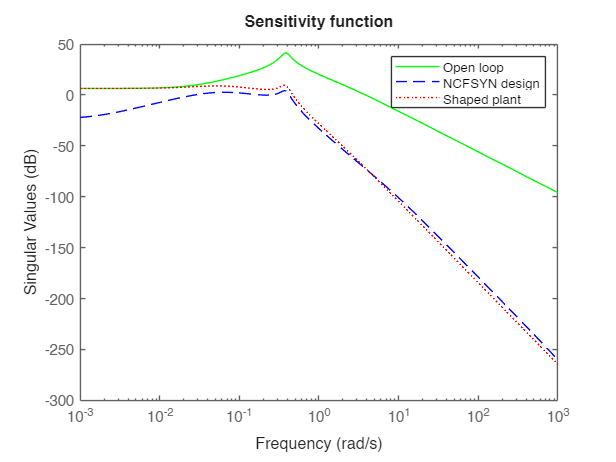

% W1_pitch = makeweight(50, 5, 0.2);
% W1_test = makeweight(6, [0.377 2], 0.01);
% W3 = makeweight(0.8, 30, 30);
% W3_pitch = makeweight(0.5, [3 9], 30);  % Penalizes KS above 10 rad/s
% Kc = 1.3;  % lag compensator gain
% zc = 0.0377;
% pc = zc/218;
% W1_test = Kc * tf([1, zc], [1, pc]);
% want to increase phase margin by 220 degrees, roughly
% a = (1/0.377) * tan(220);
% W1_test = tf([a, 1], 1)
% s = tf('s');
% LPF = 1/(s+3)^2;

% W1_pitch = 25*tf([1, 60], [100, 100]);  %W1_pitch = W1_pitch * LPF
% Prop_pitch = pidtune(P_pitch, 'pi', 0.1*2*pi);
% W1_pitch = tf([x_optimal(1), x_optimal(2)], [x_optimal(3), x_optimal(4)]);
% x_optimal(5) = 300;
% x_optimal(6) = 253;
% x_optimal(7) = 300;
% x_optimal(8) = 104;

W3_pitch = M_t_opt * ( (s / wb_t_opt) / (s/wb_t_opt + 1) )^2;
W1_pitch = M_s_opt * (1 / (s/wb_s_opt + 1))^2;
% W3_pitch = tf([x_optimal(5), x_optimal(6)], [x_optimal(7), x_optimal(8)]);
% W3_pitch = tf(1, [1, 2, 3]);
% bodemag(W1_pitch, W3_pitch);

% legend('W1', 'W3')
% grid on

% disp("OL margins")
% allmargin(P_pitch)

% cov = 0.29;
cov2 = 2.02;
% W1_PI = pidtune(P_pitch, 'pi', cov*2*pi);
% W2_PD = pidtune(P_pitch, 'p', cov2*2*pi);
% P_gain = 1.28;
% P_gain_2 = 0.97;
wb =0.821;  % desired bandwidth in rad/s
M = 20;  % DC gain
% [K_test, ~, gamma_test] = mixsyn(P_pitch, tf(wb, [1, wb/M]), [], W3_pitch);
% [K_test1, ~, gamma_test] = mixsyn(P_pitch, W1_pitch, [], W3_pitch);
% sec_ord = tf(wb, [1, wb/M]); sec_ord = sec_ord^2
[K_test, ~, gamma_test, info] = loopsyn(P_pitch, tf(wb, [1, wb/M]));
% [K_test2, ~, gamma_test, info] = loopsyn(P_pitch, W1_pitch);
% [K_test, ~, gamma_test] = ncfsyn(P_pitch);
% [K_test, ~, gamma_test] = ncfsyn(P_pitch, tf(wb, [1, wb/M]));
figure;
sigma(P_pitch, 'g', P_pitch * W1_pitch * Cinf_pitch * W2_pitch, 'b--', W2_pitch*P_pitch*W1_pitch, 'r:',{1e-3, 1e3});
title("Sensitivity function")
legend("Open loop", "NCFSYN design", "Shaped plant");
print("sigma_sens.png", "-dpng");

% [K_test, ~, gamma_test] = ncfsyn(P_pitch, tf(wb, [1, wb/M]));
% K_test = K_test;
% gamma_test
% allmargin(P_pitch*K_test)
% 
% damp(P_pitch);
% nyquistplot(P_pitch)
% get_response_graphs(P_pitch, K_test)




#### Longitudinal attitude control - loop shaping with ncfsyn


% Pre-compensator PI control
W1_long_att = pidtune(P_pitch, 'pi', 4*2*pi);  % PI controller as a pre-compensator
zeta = 0.8;  % damping ratio
omega_n = 0.383;  % natural frequency of unstable pitch pole pair
Pitch_zero = tf([1, 2*zeta*omega_n, omega_n^2], [1, 0.38])
figure;
bp_pi = bodeplot(P_pitch * W1_long_att);
bp_pi.FrequencyUnit = 'Hz';
bp_pi.XLimits = [1e-2 1e2];
hold off
grid on

% W1_long_att = W1_pitch;  % W1_pitch is the pre-compensator weight proposed by Lanzon
% dc_gain = 13.1;
% W1_long_att = tf(dc_gain, [1, dc_gain/1000]);  % Low pass filter with high DC gain

% Post-compensator to reduce all gains
reduction = 30; 
% W2_long_att = ss(1);  % unity gain
% W2_long_att = W2_pitch;
W2_long_att = ss(10^(-reduction / 20));  % scalar reduction
% W2_long_att = tf(5, [1, 3]);  % low-pass filter

[K_long_att, ~, gam_long_att] = ncf_response(P_pitch, W1_pitch);


#### Lateral attitude control - open loop response

bode(P_roll)
pre_ncf_roll = allmargin(P_roll)

W1_roll = makeweight(50, 5, 0.2);

W3_roll = makeweight(0.8, 20, 30);
bodemag(W1_roll, W3_roll)
legend('W1', 'W3')

[K_roll, ~, gamma_roll] = mixsyn(P_roll, W1_roll, [], W3_roll);
gamma_roll
allmargin(P_roll * K_roll)
get_response_graphs(P_roll, K_roll)